# Lidar 3-D Object Detection Using PointPillars Deep Learning

This example shows how to detect ojects in lidar point clouds using a pretrained PointPillars network. We are using arround 1700 front view point coulds and corresponding labels in this example.

## Step #1: Load Data and Create Datastores

Create a file datastore to load the PCD files  from the specified path using the [`pcread`](docid:vision_ref#buphpf3-1) function.

Foldername = 'Data';
path = fullfile(Foldername,'InputData');
lds = fileDatastore(path,'ReadFcn',@(x) pcread(x));
Data = readall(lds);

Load the 3-D bounding box labels of the car and truck objects.

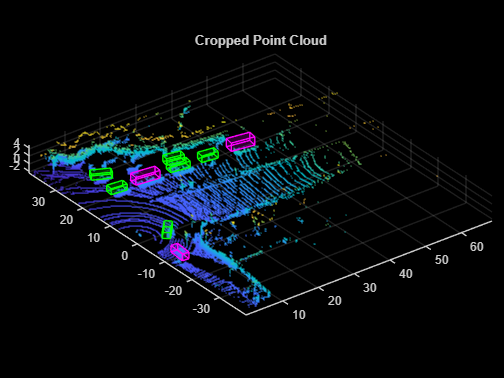

Labelpath = fullfile(Foldername,'processedlabels.mat');
Labels = load(Labelpath);
bds = boxLabelDatastore(Labels.gt);
GTLabels = Labels.gt;
cds = combine(lds,bds);

% Visualize sample data with labels.
pc = Data{1,1};
gtLabelsCar = GTLabels.Car{1};
gtLabelsTruck = GTLabels.Truck{1};
helperDisplay3DBoxesOverlaidPointCloud(pc.Location,gtLabelsCar,...
   'green',gtLabelsTruck,'magenta','Cropped Point Cloud');

## Step #2: Preprocess Data

### Split Training and Testing Data

Split the data set into training and test sets. Select 70% of the data for training the network and the rest for evaluation.

rng(1);
shuffledIndices = randperm(size(GTLabels,1),size(GTLabels,1));
idx = floor(0.7 * length(shuffledIndices));
trainData = Data(1:idx);
testData = Data(idx+1:end);

trainLabels = GTLabels(1:idx,:);
testLabels = GTLabels(idx+1:end,:);


### Data Augmentation

Randomly add a fixed number of car and truck class objects to every point cloud using the `groundTruthDataAugmentation` helper function. Use the `transform` function to apply the ground truth and custom data augmentations to the training data.

samplesToAdd = struct('Car',10,'Truck',10);
cdsAugmented = transform(cds,@(x) groundTruthDataAugmenation(x,trainData,trainLabels,samplesToAdd));

 In addition, apply the following data augmentations to every point cloud.

-  Random flipping along the x-axis

-  Random scaling by 5 percent

-  Random rotation along the z-axis from [-pi/4, pi/4]

-  Random translation by [0.2, 0.2, 0.1] meters along the x-, y-, and z-axis respectively

cdsAugmented = transform(cdsAugmented,@(x) augmentData(x));
augData = read(cdsAugmented);

groundTruthData = struct with fields:
      Car: [1×1 batchSampler]
    Truck: [1×1 batchSampler]


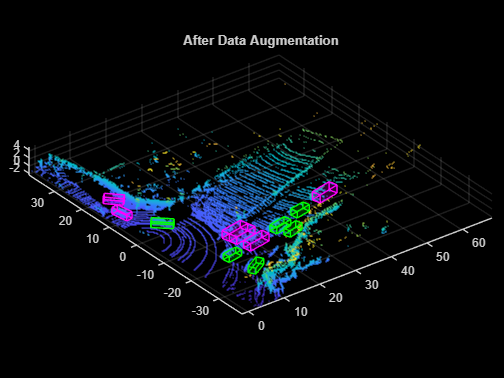

% Visualize a sample augmented data
augptCld = augData{1,1};
augLabels = augData{1,2};
augClass = augData{1,3};

labelsCar = augLabels(augClass=='Car',:);
labelsTruck = augLabels(augClass=='Truck',:);

helperDisplay3DBoxesOverlaidPointCloud(augptCld(:,1:3),labelsCar,'green',...
    labelsTruck,'magenta','After Data Augmentation');

## Step #3: Define Network

Define PointPillars network using `pointPillarsObjectDetector` function.

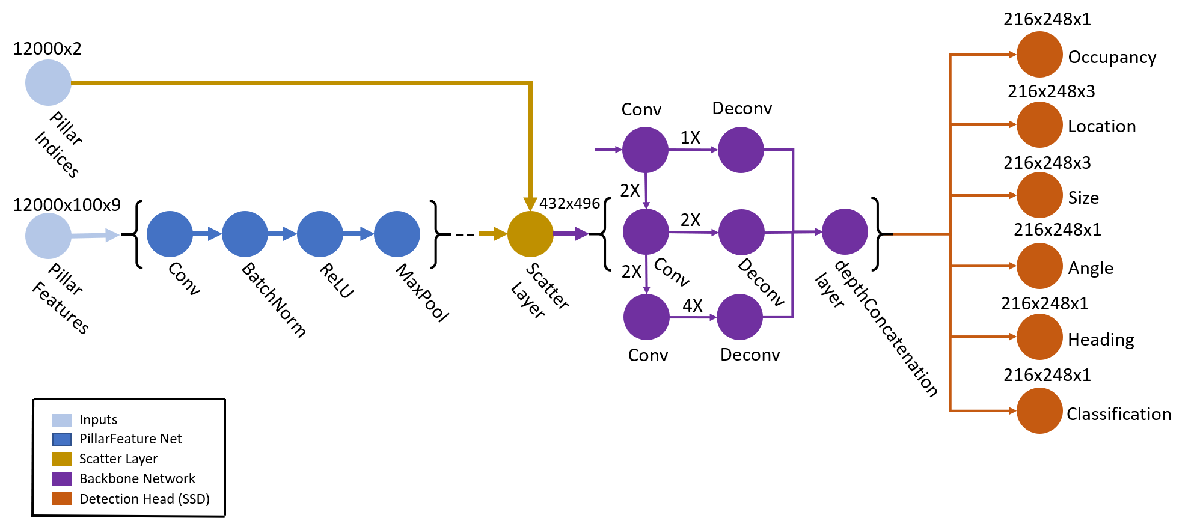

Define the anchor box dimensions based on the classes to detect. The anchor boxes are defined in the format *{length, width, height, z-center, yaw angle}.*

xMin = 0.0;     % Minimum value along X-axis.
yMin = -39.68;  % Minimum value along Y-axis.
zMin = -5.0;    % Minimum value along Z-axis.
xMax = 69.12;   % Maximum value along X-axis.
yMax = 39.68;   % Maximum value along Y-axis.
zMax = 5.0;     % Maximum value along Z-axis.
xStep = 0.16;   % Resolution along X-axis.
yStep = 0.16;   % Resolution along Y-axis.
dsFactor = 2.0; % Downsampling factor.

% Calculate the dimensions for the pseudo-image.
Xn = round(((xMax - xMin) / xStep));
Yn = round(((yMax - yMin) / yStep));

% Define point cloud parameters.
pointCloudRange = [xMin,xMax,yMin,yMax,zMin,zMax];
voxelSize = [xStep,yStep];

% Define number of prominent pillars.
P = 12000; 

% Define number of points per pillar.
N = 100;   
% Estimate anchor boxes from training data.
anchorBoxes = calculateAnchorsPointPillars(trainLabels)

anchorBoxes = 2×1 cell array
    {2×5 double}
    {2×5 double}


classNames = trainLabels.Properties.VariableNames;

% Define the PointPillars detector.
detector = pointPillarsObjectDetector(pointCloudRange,classNames,anchorBoxes,'VoxelSize', voxelSize,'NumPillars',P,'NumPointsPerPillar',N);

## Step #4: Train Network

Specify Training Options

doTraining = false;

executionEnvironment = "auto";
if canUseParallelPool
    dispatchInBackground = true;
else
    dispatchInBackground = false;
end

options = trainingOptions('adam',...
    'Plots',"none",...
    'MaxEpochs',60,...
    'MiniBatchSize',3,...
    'GradientDecayFactor',0.9,...
    'SquaredGradientDecayFactor',0.999,...
    'LearnRateSchedule',"piecewise",...
    'InitialLearnRate',0.0002,...
    'LearnRateDropPeriod',5,...
    'LearnRateDropFactor',0.8,...
    'ExecutionEnvironment',executionEnvironment,...
    'DispatchInBackground',dispatchInBackground,...
    'BatchNormalizationStatistics','moving',...
    'ResetInputNormalization',false,...
    'CheckpointPath',tempdir);

Train Model

if doTraining    
    [detector,info] = trainPointPillarsObjectDetector(cdsAugmented,detector,options); % The dataset we are using is very small. For better results, use larger datasets
else
    pretrainedDetector = load('pretrainedPointPillarsDetector.mat','detector');
    detector = pretrainedDetector.detector;
end

## Step #5: Generate Detections

Use the trained network to detect objects in the test data:

- Read the point cloud from the test data.

- Run the detector on the test point cloud to get the predicted bounding boxes and confidence scores.

- Display the point cloud with bounding boxes using the `helperDisplay3DBoxesOverlaidPointCloud` helper function, defined at the end of the example

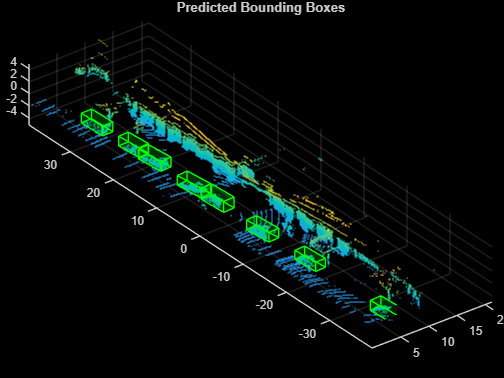

ptCloud = testData{7,1};
gtLabels = testLabels(7,:);

% Specify the confidence threshold to use only detections with
% confidence scores above this value.
confidenceThreshold = 0.5;
[box,score,labels] = detect(detector,ptCloud,'Threshold',confidenceThreshold);

boxlabelsCar = box(labels'=='Car',:);
boxlabelsTruck = box(labels'=='Truck',:);

% Display the predictions on the point cloud.
helperDisplay3DBoxesOverlaidPointCloud(ptCloud.Location,boxlabelsCar,'green',...
    boxlabelsTruck,'magenta','Predicted Bounding Boxes');

### References

[1] Lang, Alex H., Sourabh Vora, Holger Caesar, Lubing Zhou, Jiong Yang, and Oscar Beijbom. "PointPillars: Fast Encoders for Object Detection From Point Clouds." In *2019 IEEE/CVF Conference on Computer Vision and Pattern Recognition *(CVPR), 12689-12697. Long Beach, CA, USA: IEEE, 2019. [https://doi.org/10.1109/CVPR.2019.01298](https://doi.org/10.1109/CVPR.2019.01298).

[2] Hesai and Scale. PandaSet. [https://scale.com/open-datasets/pandaset](https://scale.com/open-datasets/pandaset).

*Copyright 2020 The MathWorks, Inc.*